# `第 6 次作业`

## 1. `阅读代码并给出有关参数值的理论推导。具体要求是：`

`（`1`）对于文档`“`基本幅度调制`— `待调信号、载波信号、调制信号` - `简化`.pdf”`，推算代码中的采样频率`fs`等于多少？时域`sinc`函数的主瓣内会采样到多少个样点？`

`待调信号、载波信号、调制信号的频谱：`

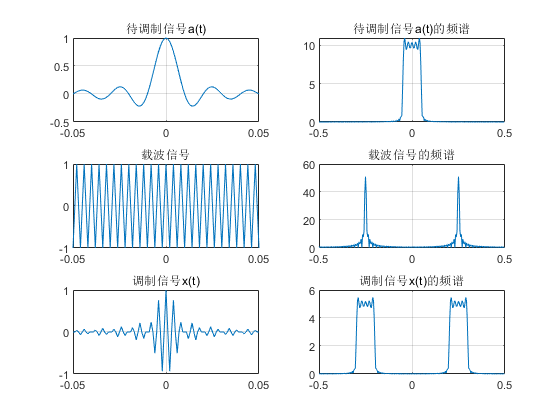

%-------------------------------------------------------------
% exa090300_1.m,   for fig. 9.3.1,
%-------------------------------------------------------------
clear all;

t0=.1; 
ts=.001;                  % ts=0.001 = 0.001x1
fc=250;                   % 载波频率 250Hz，

t=[-t0/2:ts:t0/2];
m=sinc(100*t);            % 时域 sinc 函数，频域窗函数；
                          % 时域函数： sin(100*pi*t)/(100*pi*t)
                          % sinc 函数的主瓣内有 ? 点， 给出理论推导
c=cos(2*pi*fc*t);         % fs= ?

% 信号的调幅；
u=m.*c;

figure(1)
subplot(3,2,1)
plot(t,m(1:length(t)));grid;title('待调制信号a(t)');
subplot(3,2,3)
plot(t,c(1:length(t)));grid;title('载波信号');
subplot(3,2,5)
plot(t,u(1:length(t)));grid;title('调制信号x(t)');
f=-0.5:1/256:0.5-1/256;

% 求待调信号、载波信号和调制信号的频谱；
M=fft(m,256);
C=fft(c,256);
U=fft(u,256);

subplot(322)
plot(f,abs(fftshift(M)));grid;title('待调制信号a(t)的频谱');
subplot(324)
plot(f,abs(fftshift(C)));grid;title('载波信号的频谱');
subplot(326)
plot(f,abs(fftshift(U)));grid;title('调制信号x(t)的频谱');

`    代码中的采样频率 `fs = $\frac{1}{t_s}$ = $\frac{1}{0.001}$ = 1k Hz，抽样间隔N = $\frac{t_0}{t_s}$ = $\frac{0.1}{0.001}=100$，主瓣宽度为$\frac{1}{100}-(-\frac{1}{100})$ = $\frac{1}{50}$，`时域`sinc`函数的主瓣内会采样到`$\frac{1}{50}\times1k = 20$`个样点。`

`（`2`）对于文档`“`信号调制方式与仿真` - `简化`.pdf”`，推算代码中的待调信号的频率`f0`、模拟信号一个周期内的采样点数`N`、采样后得到的数字信号的数字角频率`w0`各是多少？`

`相关的理论内容，可以参考教材`9.3`节。`

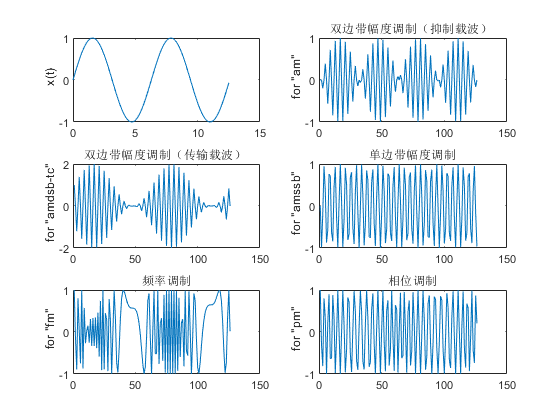

%-----------------------------------------------------------------
% exa090802_modulate.m,  for example 9.8.2
% to test modulate.m;
%
% 注：此程序在 MATLAB 5.3 下可以运行，在 MATLAB 6.1下可能无法运行！
%-----------------------------------------------------------------
clear all;

% 得到待调数据；
t=0:.1:4*pi;               % 这 2 行代码是参考代码中给出的。分析
x=sin(t);                  % 给定参数： fs=1；
                           % 周期点数： w0=？ f0=？ N=？
fs=1;
fc=.25;                    % 载波信号频率

subplot(321)
plot(0:.1:4*pi,x)
ylabel('  x(t)')

% 以下是不同的调制方式；
y=modulate(x,fc,fs,'am');
subplot(322)
plot(y)
ylabel('  for "am"')
title("双边带幅度调制（抑制载波） ")

y=modulate(x,fc,fs,'amdsb-tc');
subplot(323)
plot(y)
ylabel('  for "amdsb-tc"')
title("双边带幅度调制（传输载波） ")

y=modulate(x,fc,fs,'amssb');
subplot(324)
plot(y)
ylabel('  for "amssb"')
title("单边带幅度调制")

y=modulate(x,fc,fs,'fm');
subplot(325)
plot(y)
ylabel('  for "fm"')
title("频率调制")

y=modulate(x,fc,fs,'pm');
subplot(326)
plot(y)
ylabel('  for "pm"')
title("相位调制")

`    待调信号的频率`f0 = $\frac{1}{2\pi}$；`模拟信号一个周期内的采样点数`N = $\frac{2\pi}{0.1}$ = $20\pi$ = 62；`采样后得到的数字信号的数字角频率`w0 = $\frac{0.1}{2\pi}$ = $\frac{1}{20\pi}$。

## 2. `利用下面提供的代码对``第一次大作业``中的语音文件（`bluesky1.wav`）里的语音数据做频谱分析，并与频谱的`DFT`直接计算方式和`MATLAB`中的`fft`函数计算方式做时间开销的比较。要求提供完整的代码。`

close all;
clear all;

[x,Fs] = audioread("bluesky1.wav",'native');x=x';
p = nextpow2(length(x));
n = 2^p;
tic,X0 = fft(x,n),toc;

X0 = 	1.0e+06 *

  -0.0350 + 0.0000i   0.0013 - 0.0039i   0.0126 - 0.0071i  -0.0034 - 0.0103i  -0.0085 - 0.0072i  -0.0187 - 0.0044i   0.0047 + 0.0078i   0.0007 + 0.0056i  -0.0032 + 0.0012i  -0.0070 - 0.0010i   0.0021 + 0.0139i   0.0110 + 0.0095i   0.0125 + 0.0049i  -0.0012 - 0.0101i   0.0056 - 0.0010i   0.0046 + 0.0031i   0.0071 + 0.0051i   0.0014 - 0.0207i  -0.0077 - 0.0097i  -0.0107 + 0.0009i  -0.0128 + 0.0177i  -0.0034 + 0.0040i   0.0003 + 0.0043i  -0.0001 + 0.0030i   0.0016 + 0.0156i   0.0098 + 0.0059i   0.0060 - 0.0075i   0.0109 - 0.0203i  -0.0091 + 0.0006i  -0.0071 - 0.0091i  -0.0018 - 0.0100i   0.0003 - 0.0125i  -0.0185 - 0.0071i  -0.0096 + 0.0049i  -0.0063 + 0.0045i   0.0068 - 0.0023i  -0.0054 + 0.0075i  -0.0041 + 0.0073i  -0.0061 + 0.0099i   0.0200 + 0.0133i   0.0091 + 0.0009i   0.0005 - 0.0040i  -0.0075 - 0.0124i  -0.0002 - 0.0096i   0.0021 + 0.0056i  -0.0036 - 0.0055i  -0.0231 - 0.0054i  -0.0119 + 0.0088i  -0.0012 + 0.0094i   0.0137 + 0.0208i


时间已过 0.002108 秒。


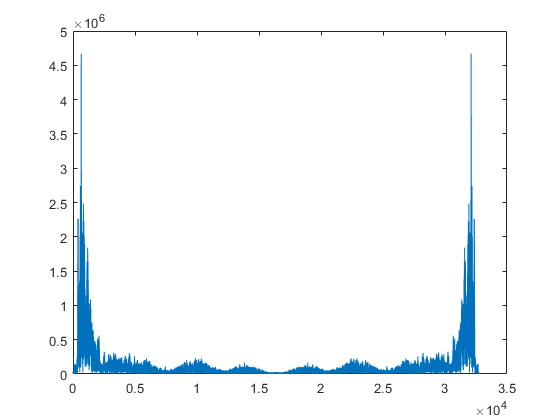

plot(abs(X0));

close all;
clear all;

[x,Fs] = audioread("bluesky1.wav",'native');
x=double(x');
tic,X1 = MATLAB_ditfft(x),toc;

X1 = 	1.0e+06 *

   -0.0350    0.0456   -0.0223    0.0685   -0.0531    0.0007   -0.1155   -0.0007    0.0543   -0.2082    0.2009   -0.0200   -0.1157    0.0892   -0.1067    0.1349   -0.2239   -0.1822    0.0805    0.1535    0.1641    0.0819    0.0678    0.0206    0.1573    0.0487    0.0399   -0.0093   -0.2369   -0.0388   -0.1884    0.0517    0.1643    0.1520    0.1690    0.2424   -0.0593   -0.3963    0.1421   -0.0099   -0.3271    0.0628   -0.2980   -0.0027   -0.0584    0.0423    0.0473    0.1095    0.0418    0.1392


时间已过 0.479648 秒。


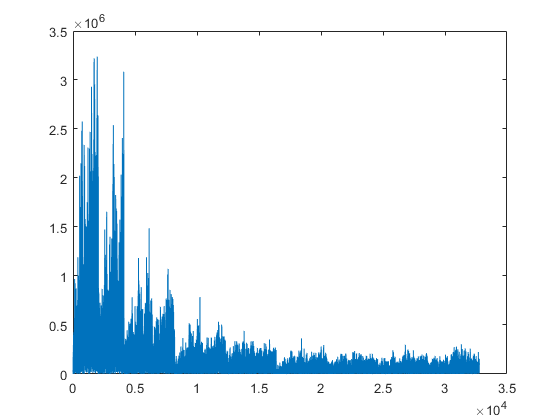

plot(abs(X1));

close all;
clear all;

[x,Fs] = audioread("bluesky1.wav",'native');
x=double(x');
tic,X2 = MATLAB_dft(x),toc;

X2 = 	1.0e+06 *

  -0.0350 + 0.0000i   0.0001 - 0.0035i   0.0112 - 0.0085i  -0.0044 - 0.0098i  -0.0095 - 0.0063i  -0.0218 + 0.0001i   0.0028 + 0.0031i   0.0013 + 0.0035i  -0.0038 + 0.0020i  -0.0119 + 0.0025i   0.0025 + 0.0107i   0.0103 + 0.0039i   0.0153 - 0.0023i  -0.0052 - 0.0026i   0.0003 - 0.0047i   0.0043 - 0.0029i   0.0167 - 0.0050i  -0.0085 - 0.0146i  -0.0145 - 0.0085i  -0.0156 - 0.0025i   0.0045 + 0.0092i   0.0002 + 0.0067i   0.0006 + 0.0037i  -0.0049 + 0.0058i   0.0119 + 0.0052i   0.0168 - 0.0059i   0.0160 - 0.0064i  -0.0126 - 0.0128i   0.0027 - 0.0103i   0.0031 - 0.0048i   0.0015 - 0.0054i  -0.0147 - 0.0111i  -0.0110 + 0.0062i  -0.0051 + 0.0055i   0.0071 + 0.0058i  -0.0092 + 0.0070i  -0.0054 + 0.0069i  -0.0059 + 0.0084i   0.0173 + 0.0171i   0.0078 + 0.0007i   0.0001 - 0.0049i  -0.0071 - 0.0129i  -0.0004 - 0.0097i   0.0031 + 0.0049i  -0.0030 - 0.0054i  -0.0236 - 0.0016i  -0.0120 + 0.0104i  -0.0027 + 0.0092i   0.0203 + 0.0160i  -0.0033 - 0.0026i


时间已过 51.427091 秒。


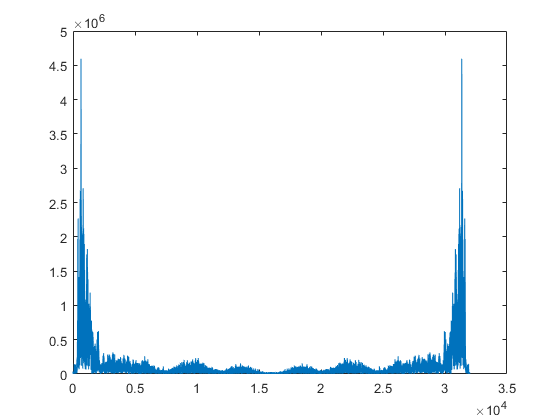

plot(abs(X2));

function y = MATLAB_ditfft(x)
%UNTITLED 此处显示有关此函数的摘要
    %   此处显示详细说明
    m=nextpow2(length(x));
    N=2^m;  %求x的长度对应的2的最低次幂m
    if length(x)<N
        x = [x,zeros(1,N-length(x))];
        %若x的长度不是2的幂，补零到2的整数幂
    end
    %nxd = bin2dec(fliplr(dec2bin([1:N]-1,m)))+1;
    %求1:2^m数列的倒序
    nxd0 = dec2bin([1:N]-1,m);
    nxd1 = fliplr(nxd0);
    nxd = bin2dec(nxd1)+1;
    y=x(nxd);                               %将x倒序排列作为y的初始值
    for mm=1:m                          %将DFT作m次基2分解，从左到右，对每次分解作DFT运算
        Nmr = 2^mm;u=1;            %旋转因子u初始化为WN^0=1
        WN=exp(-1i*2*pi/Nmr);    %本次分解的基本DFT因子WN=exp(-i*2*pi/Nmr)
        for j=1:Nmr/2                    %本次跨越间隔内的各次蝶形运算
            for k=j:Nmr:N                %本次蝶形运算的跨越间隔为Nmr=2^mm
                kp = k+Nmr/2;          %本次蝶形运算的对应单元下标
                t = y(kp)*abs(u);                %蝶形运算的乘积项
                y(kp) = y(k)-t;             %蝶形运算
                y(k) = y(k)+t;              %蝶形运算
            end
            u=u*WN;                       %修改旋转因子，多乘一个基本DFT因子WN
        end
    end
end

function y = MATLAB_dft(x)
%UNTITLED2 此处显示有关此函数的摘要
%   x为给定时间序列，y为x的离散傅里叶变换
    N = length(x);            %输入序列的长度
    %n = 0:N-1;k=n;           %确定时域位置序列n和频域位置序列k
    %WN = exp(-1i*2*pi/N);%计算DFT所需的旋转因子
    %nk = n'*k;                   %构成旋转因子矩阵
    %WNnk = WN.^nk;      %构成旋转因子矩阵
    %Xk = x*WNnk;            %按照DFT定义计算x的傅里叶变换
    y(1:N) = 0;k=0:N-1;
    for n = 1:N
        y = y + x(n)*exp(-1i*2*pi*(n-1)*k/N);
    end%y=Xk;
end